# Adaptive filtering 

## Data construction 

fs = 500; % Sampling Rate
N = 5000; % No. of Samples
snr = 10; 
a = 0.2;
phi = pi/3;
phi1 = pi/6;
phi2 = pi/4;

t = linspace(0,10,N)'; %time vector with fs = 500 Hz
s = sawtooth(2*pi*2*t(1:N,1),0.5); % Clean Signal
n1 = 0.2 * sin(2*pi*50*t(1:N/2,1)-phi);
n2 = 0.3 * sin(2*pi*100*t(N/2+1:end,1)-phi);
nwg = s - awgn(s,snr,'measured'); % Added Gaussian noise

sin_noise = [n1; n2];

n_n = nwg + sin_noise; % Total Noise Added
y_i_n = s; 
r_n = a * (nwg + sin(2*pi*50*t+phi1) + sin(2*pi*50*t+phi2)); % Reference Noise Signal

x_n = y_i_n + n_n; % Input signal


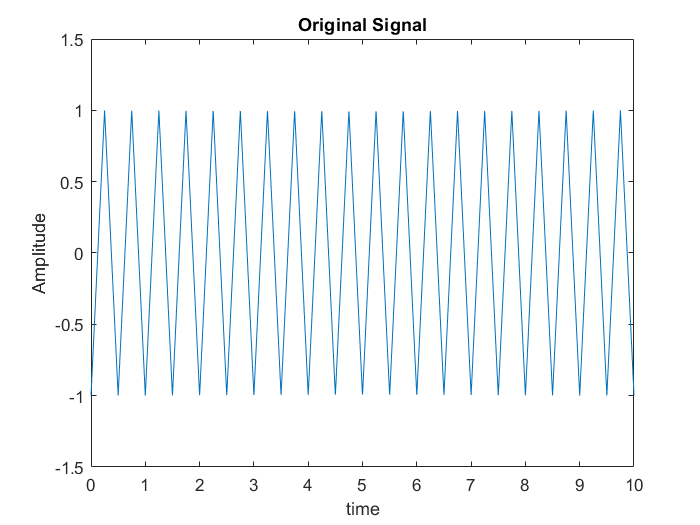

figure;

plot(t, y_i_n);
title('Original Signal');
xlabel('time');
ylabel('Amplitude');
ylim([-1.5,1.5]);

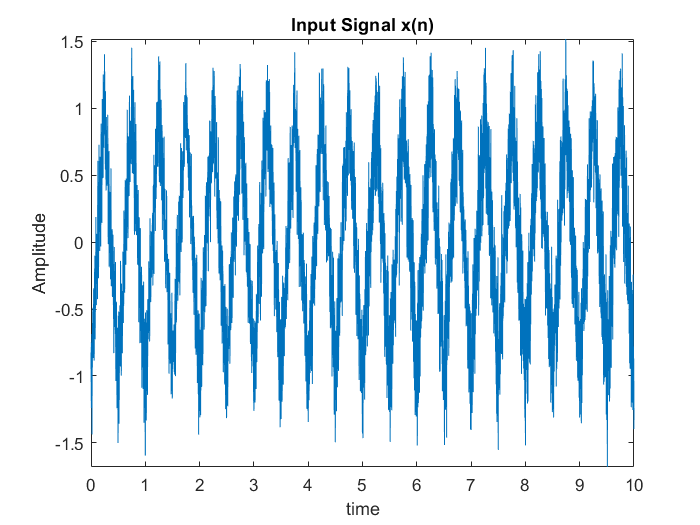


figure;

plot(t, x_n);
title('Input Signal x(n)');
xlabel('time');
ylabel('Amplitude');
ylim([-1.5,1.5]);

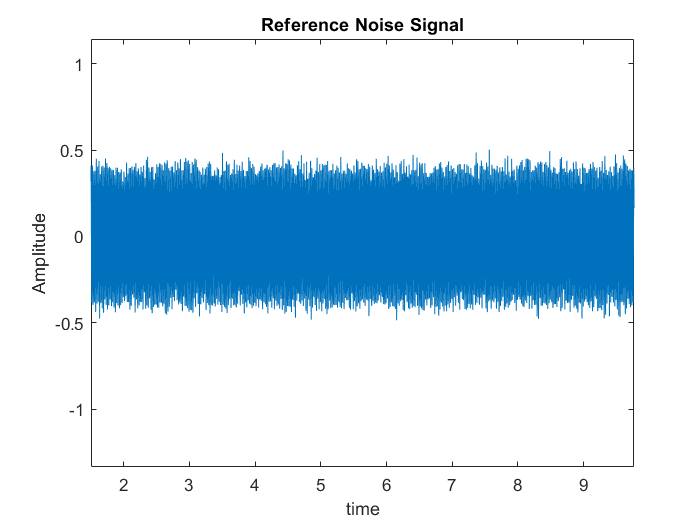


figure;

plot(t, r_n);
title('Reference Noise Signal');
xlabel('time');
ylabel('Amplitude');
ylim([-1.5,1.5]);

## 2.1 LMS method

M = 40; % Filter order

% R_NN_ = xcorr(r_n, M-1, 'biased');   
% R_NN = toeplitz(R_NN_(order:end));
% max_mu = max(eig(R_NN));

% input_signal_power  = mean(x_n.^2);
% max_mu = 2/(20*input_signal_power*M);
% disp(['Max mu: ', num2str(max_mu)]); % Maximum mu that controls stability and rate of convergence

Max mu: 0.0014423


mu = 0.05;

[e_n, est_noise] = lms_filter(x_n, r_n, M,mu); % FIltering using the lms filter. 

% e_n is the filtered signal, est_noise is the estimated noise from the
% filter.

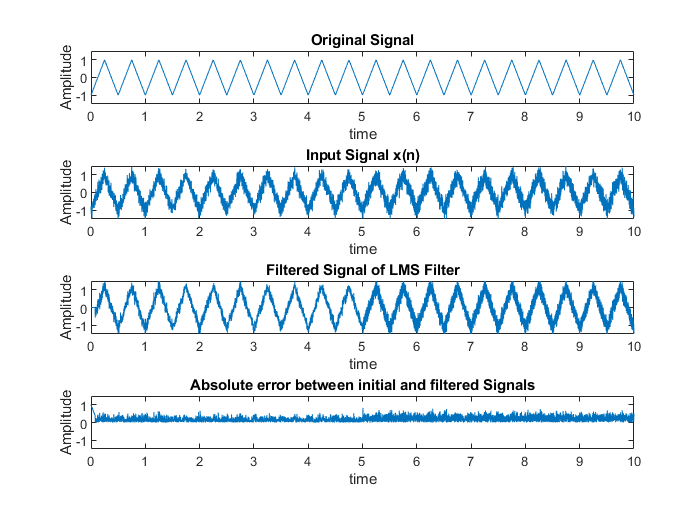

figure;
subplot(4, 1, 1);
plot(t, y_i_n);
title('Original Signal');
xlabel('time');
ylabel('Amplitude');
ylim([-1.5,1.5]);

subplot(4, 1, 2);
plot(t, x_n);
title('Input Signal x(n)');
xlabel('time');
ylabel('Amplitude');
ylim([-1.5,1.5]);

subplot(4, 1, 3);
plot(t, e_n);
title('Filtered Signal of LMS Filter');
xlabel('time');
ylabel('Amplitude');
ylim([-1.5,1.5]);

subplot(4, 1, 4);
plot(t, abs(y_i_n - e_n));
title('Absolute error between initial and filtered Signals');
xlabel('time');
ylabel('Amplitude');
ylim([-1.5,1.5]);

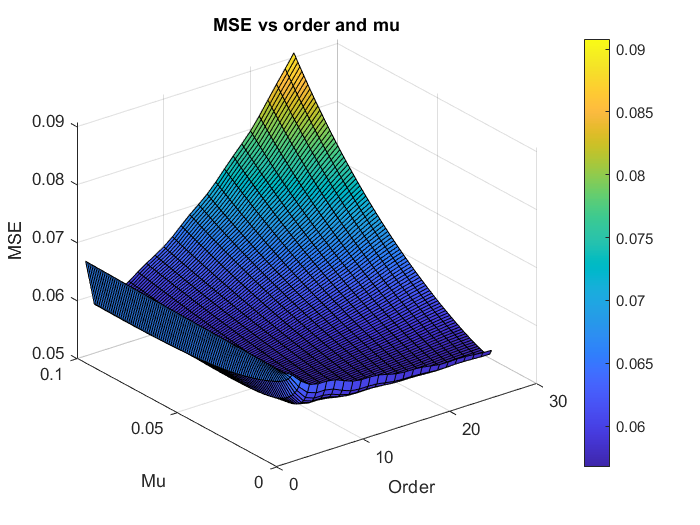

% Calculating the mu and order with minimum error

mu_var_arr = 0.001:0.001:0.1;
mse_array = nan(100,length(mu_var_arr));

for M_var = 1:25 
    
    for mu_var = 1:length(mu_var_arr)
        
        [e_n, est_noise] = lms_filter(x_n, r_n, M_var,mu_var_arr(mu_var));
        mse_array(M_var,mu_var) = mse(e_n(M_var:end),y_i_n(M_var:end));
    end
    
end

% Create a meshgrid for plotting
[M_var_mesh, mu_var_mesh] = meshgrid(1:100, mu_var_arr);

% Plot the MSE array as a surface plot
figure;
surf(M_var_mesh, mu_var_mesh, mse_array');  % Transpose mse_array for correct orientation
xlabel('Order');
ylabel('Mu');
zlabel('MSE');
title('MSE vs order and mu');
colorbar;  

% Extracting the order and mu for optimum filter

[min_mse_value, min_idx] = min(mse_array(:));
[M_var_min_idx, mu_var_min_idx] = ind2sub(size(mse_array), min_idx);
min_M_var = M_var_min_idx;
min_mu_var = mu_var_arr(mu_var_min_idx);

disp(['Order: ', num2str(min_M_var), '     Mu: ', num2str(min_mu_var)]);

Order: 9     Mu: 0.01


## 2.2 RLS Method

lambda = 0.999; % Forgetting factor
order = 10; % Filter order

[e_n, est_noise] = rls_filter(r_n,x_n,lambda,order); % Filtering the signal


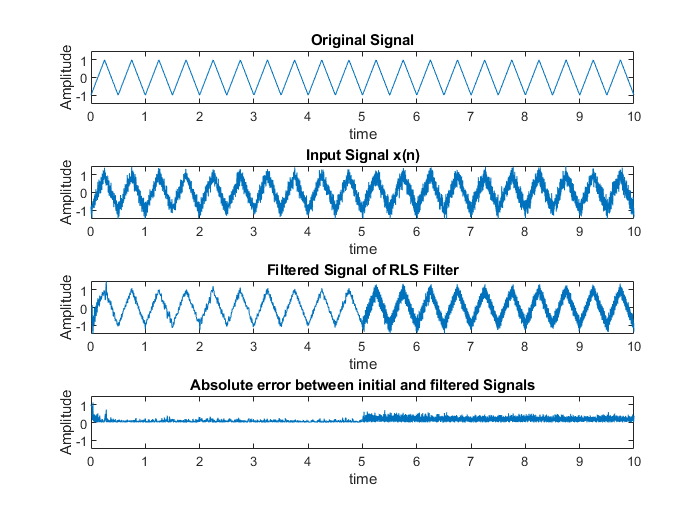

figure;
subplot(4, 1, 1);
plot(t, y_i_n);
title('Original Signal');
xlabel('time');
ylabel('Amplitude');
ylim([-1.5,1.5]);

subplot(4, 1, 2);
plot(t, x_n);
title('Input Signal x(n)');
xlabel('time');
ylabel('Amplitude');
ylim([-1.5,1.5]);

subplot(4, 1, 3);
plot(t, e_n);
title('Filtered Signal of RLS Filter');
xlabel('time');
ylabel('Amplitude');
ylim([-1.5,1.5]);

subplot(4, 1, 4);
plot(t, abs(y_i_n - e_n));
title('Absolute error between initial and filtered Signals');
xlabel('time');
ylabel('Amplitude');
ylim([-1.5,1.5]);

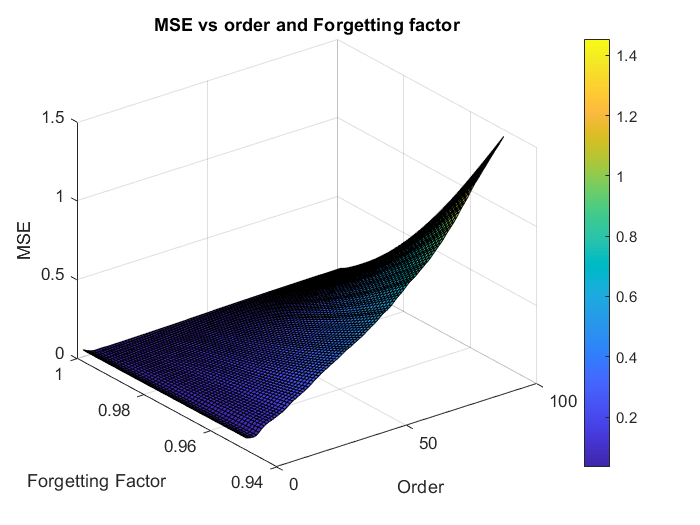

% Calculating the values for forgetting factor and order for optimum
% filtering based on the MSE values

lambda_arr = 0.95:0.001:0.999; % Region of lambda being considered

mse_array_rls = nan(100,length(lambda_arr));

for order_var = 1:100 
    
    for lambda_var = 1:length(lambda_arr)
        
        [e_n_i, est_noise_i] = rls_filter(r_n,x_n,lambda_arr(lambda_var),order_var);
                      
        mse_array_rls(order_var,lambda_var) = mse(e_n_i(order_var+1:end),y_i_n(order_var+1:end));
    end
    
end

% Create a meshgrid for plotting
[order_var_mesh, lambda_var_mesh] = meshgrid(1:100, lambda_arr);

% Plot the MSE array as a surface plot
figure;
surf(order_var_mesh, lambda_var_mesh, mse_array_rls');  % Transpose mse_array for correct orientation
xlabel('Order');
ylabel('Forgetting Factor');
zlabel('MSE');
title('MSE vs order and Forgetting factor');
colorbar;  

% Extracting the order and mu for optimum filter

[min_mse_value, min_idx_rls] = min(mse_array_rls(:));
[order_var_min_idx, lambda_var_min_idx] = ind2sub(size(mse_array_rls), min_idx_rls);
min_order_var = order_var_min_idx;
min_lambda_var = lambda_arr(lambda_var_min_idx);

disp(['Order: ', num2str(min_order_var), '     Mu: ', num2str(min_lambda_var)]);

Order: 15     Mu: 0.999


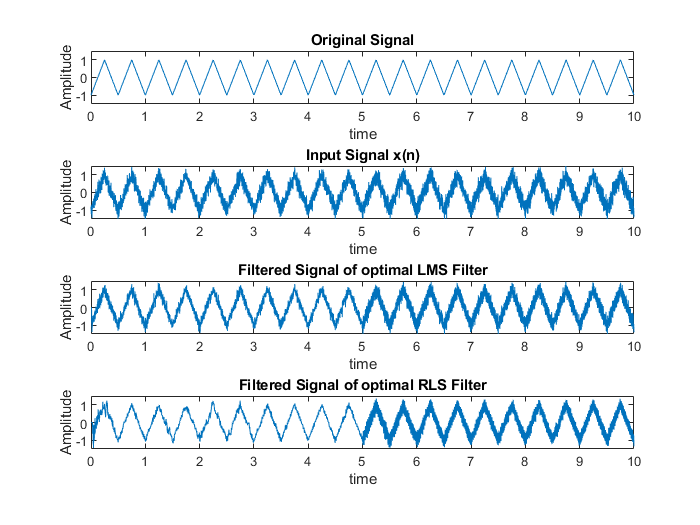

% Comparing optimal filtering of LMS and RLS

[e_n_opt_lms, est_noise_opt_lms] = lms_filter(x_n, r_n, min_M_var,min_mu_var);
[e_n_opt_rls, est_noise_opt_lms] = rls_filter(r_n,x_n,min_lambda_var,min_order_var);

figure;
subplot(4, 1, 1);
plot(t, y_i_n);
title('Original Signal');
xlabel('time');
ylabel('Amplitude');
ylim([-1.5,1.5]);

subplot(4, 1, 2);
plot(t, x_n);
title('Input Signal x(n)');
xlabel('time');
ylabel('Amplitude');
ylim([-1.5,1.5]);

subplot(4, 1, 3);
plot(t, e_n_opt_lms);
title('Filtered Signal of optimal LMS Filter');
xlabel('time');
ylabel('Amplitude');
ylim([-1.5,1.5]);

subplot(4, 1, 4);
plot(t, e_n_opt_rls);
title('Filtered Signal of optimal RLS Filter');
xlabel('time');
ylabel('Amplitude');
ylim([-1.5,1.5]);

% Testing using idealECG

load("idealECG");
y_i_ecg = idealECG'; 
t = (0:length(idealECG)-1)'/500;
N = length(idealECG);

n1 = 0.2 * sin(2*pi*50*t(1:N/2,1)-phi);
n2 = 0.3 * sin(2*pi*100*t(N/2+1:end,1)-phi);
nwg = idealECG' - awgn(idealECG',snr,'measured');

sin_noise = [n1; n2];

n_n = nwg + sin_noise;

x_n_ecg = y_i_ecg + n_n;

r_n = a * (nwg + sin(2*pi*50*t+phi1) + sin(2*pi*50*t+phi2));

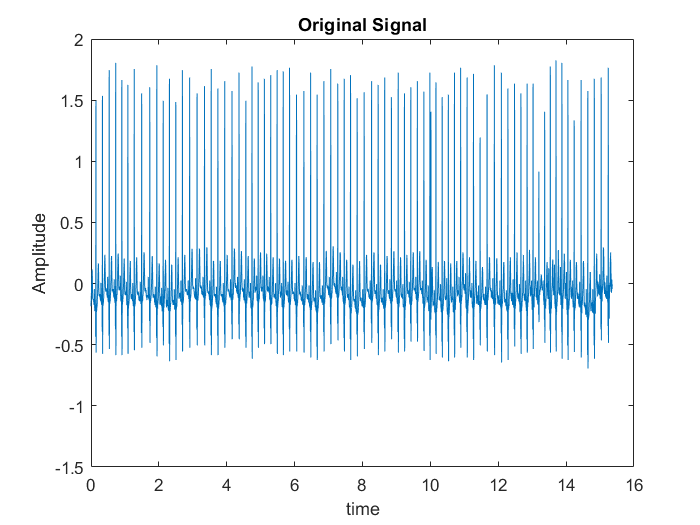

figure;

plot(t, y_i_ecg);
title('Original Signal');
xlabel('time');
ylabel('Amplitude');
ylim([-1.5,2]);

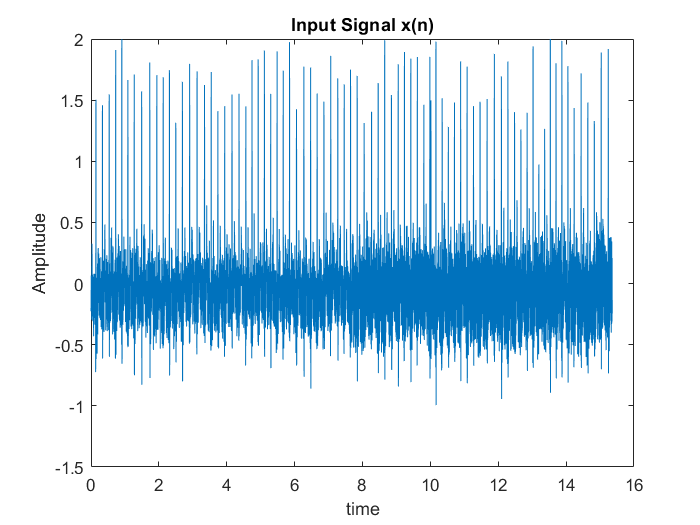


figure;

plot(t, x_n_ecg);
title('Input Signal x(n)');
xlabel('time');
ylabel('Amplitude');
ylim([-1.5,2]);

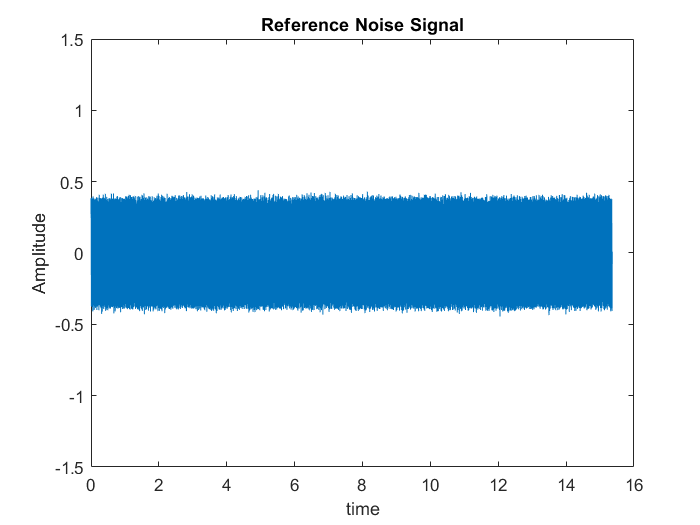


figure;

plot(t, r_n);
title('Reference Noise Signal');
xlabel('time');
ylabel('Amplitude');
ylim([-1.5,1.5]);

%Filtering using LMS

[e_n_ecg_lms, est_noise_ecg_lms] = lms_filter(x_n_ecg, r_n, min_M_var,min_mu_var);
mse_lms_ecg = mse(e_n_ecg_lms, y_i_ecg);

%Filtering using RLS

[e_n_ecg_rls, est_noise_ecg_rls] = rls_filter(r_n,x_n_ecg,min_lambda_var,min_order_var);
mse_rls_ecg = mse(e_n_ecg_rls, y_i_ecg);

disp(['MSE LMS: ',num2str(mse_lms_ecg),'     MSE RLS: ',num2str(mse_rls_ecg)]);

MSE LMS: 0.036266     MSE RLS: 0.025717


MSE LMS: 0.033334     MSE RLS: 0.025877


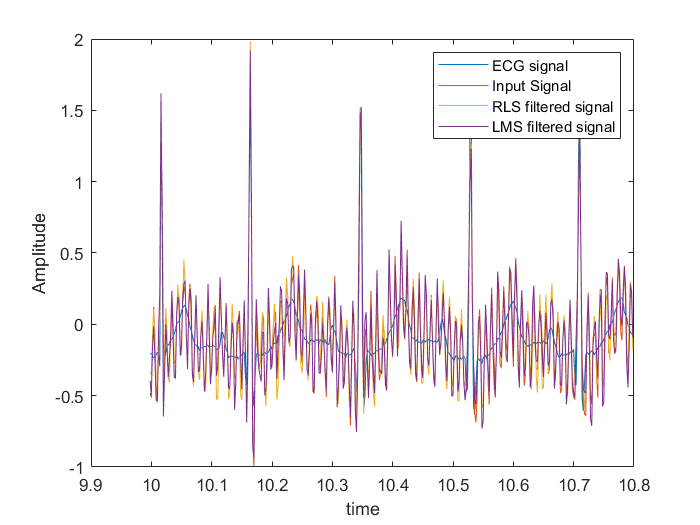


figure;


plot(t(5000:5400), y_i_ecg(5000:5400));
hold on;
plot(t(5000:5400), x_n_ecg(5000:5400));
hold on;
plot(t(5000:5400), e_n_ecg_rls(5000:5400));
hold on;
plot(t(5000:5400), e_n_ecg_lms(5000:5400));

xlabel('time');
ylabel('Amplitude');
legend('ECG signal','Input Signal','RLS filtered signal','LMS filtered signal');

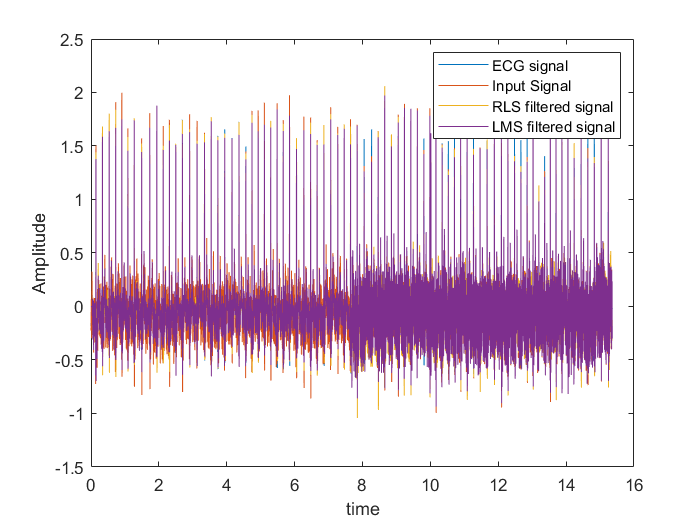

figure;


plot(t, y_i_ecg);
hold on;
plot(t, x_n_ecg);
hold on;
plot(t, e_n_ecg_rls);
hold on;
plot(t, e_n_ecg_lms);

xlabel('time');
ylabel('Amplitude');
legend('ECG signal','Input Signal','RLS filtered signal','LMS filtered signal');